# Chap8   蚁群算法、时间序列

# 蚁群算法

旅行商问题(Traveling Saleman Problem，TSP)是车辆路径调度问题(VRP)的特例，由于数学家已证明TSP问题是NP难题，因此，VRP也属于NP难题。旅行商问题（TSP）又译为旅行推销员问题、货郎担问题，简称为TSP问题，是最基本的路线问题，该问题是在寻求单一旅行者由起点出发，通过所有给定的需求点之后，最后再回到原点的最小路径成本。

1).经典精确算法:穷举法、线性规划算法、动态规划算法、分支定界算法等运筹学中的传统算法，这些算法复杂度一般都很大，只适用于求解小规模问题。

2).近似算法：当问题规模较大时，其所需的时间成级数增长，这是我们无法接受的，算法求解问题的规模受到了很大的限制，一个很自然的想法就是牺牲精确解法中的最优性，去寻找一个好的时间复杂度我们可以容忍的，同时解的质量我们可以接受的算法．基于这一思想所设计出的算法统称为近似算法。如插入算法，最邻近算法等。

3).智能算法：随着科学技术和生产的不断发展，许多实际问题不可能在合理的时间范围内找到全局最优解，这就促使了近代最优化问题求解方法的产生。随着各种不同搜索机制的启发式算法相继出现，如禁忌搜索、遗传算法、模拟退火算法、人工神经网络、进化策略、进化编程、粒子群优化算法、蚁群优化算法和免疫计算等。

        蚁群算法是受到对真实蚂蚁群觅食行为研究的启发而提出。生物学研究表明：一群相互协作的蚂蚁能够找到食物和巢穴之间的最短路径,而单只蚂蚁则不能。生物学家经过大量细致观察研究发现,蚂蚁个体之间的行为是相互作用相互影响的。蚂蚁在运动过程中,能够在它所经过的路径上留下一种称之为信息素的物质,而此物质恰恰是蚂蚁个体之间信息传递交流的载体。

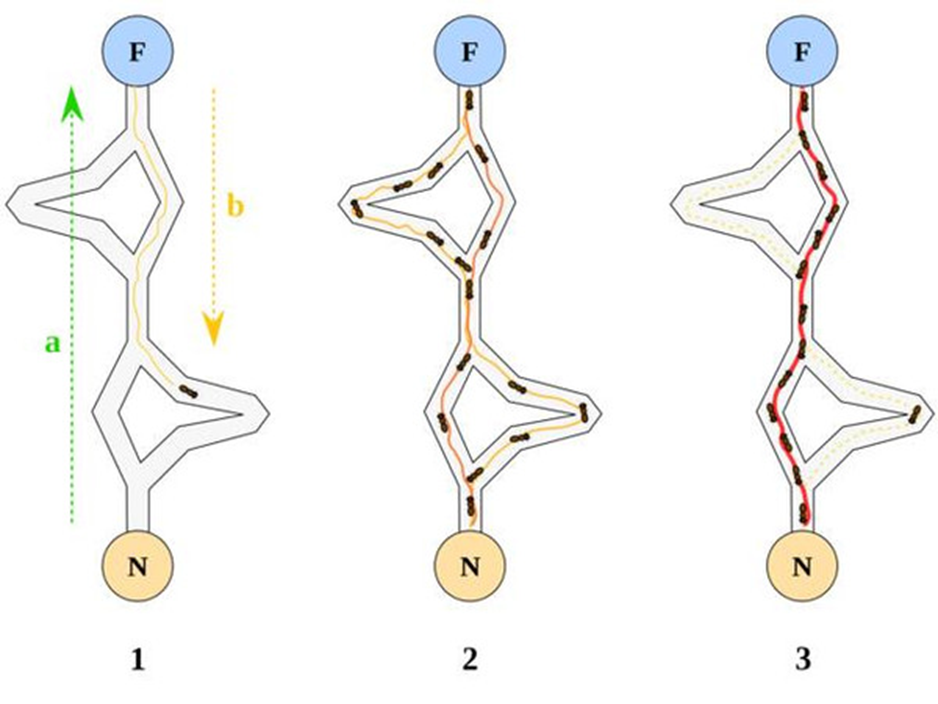

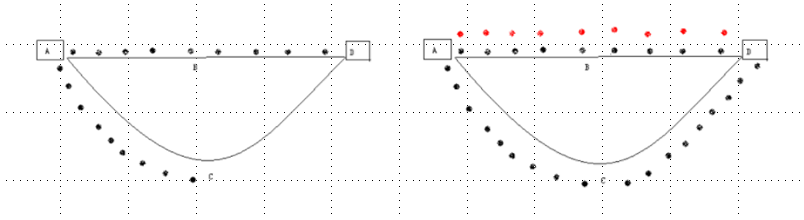

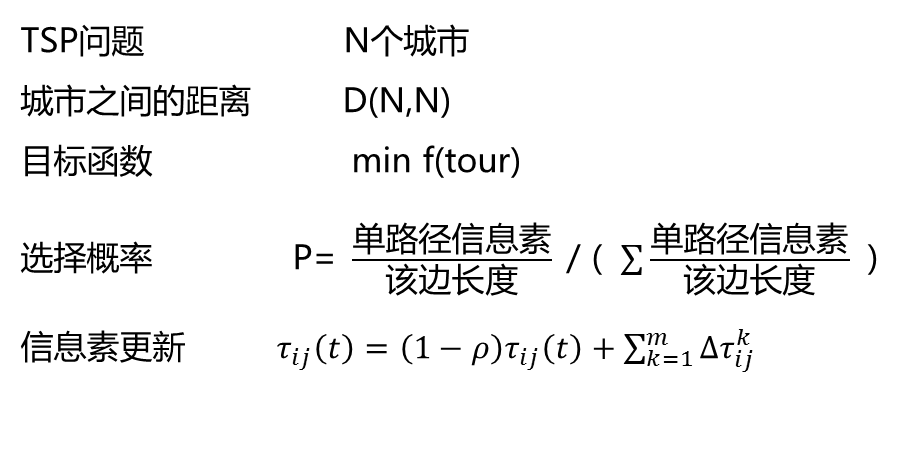

终止条件             1，最大迭代次数

                           2，趋同

                           3，运行时间

蚁群算法处理的都是离散问题（城市都是离散的），对于连续问题（比如求一个实数）很难操作，如果是一个实数，可参考的操作方式如下：

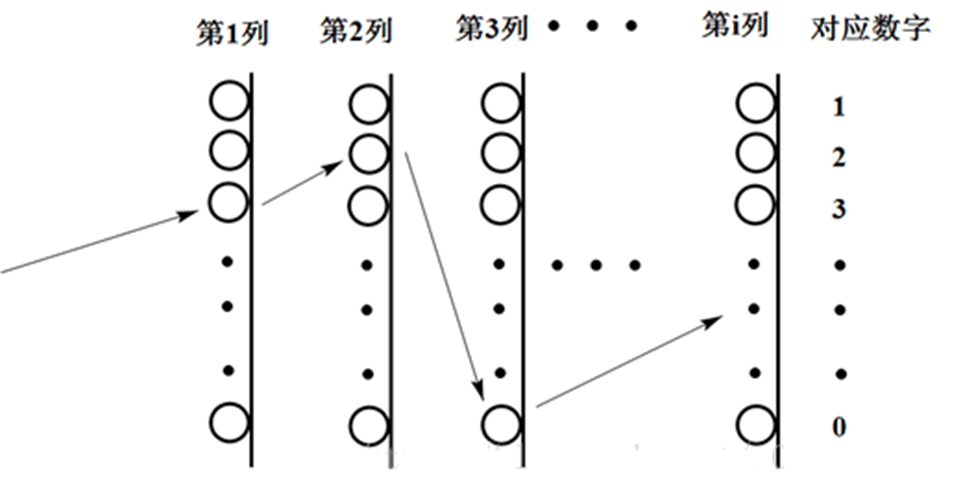

蚁群算法演示程序

aco.m

# 时间序列

`时间序列是按时间顺序排列的、随时间变化且相互关联的数据序列。分析时间序列的方法构成数据分析的一个重要领域，即时间序列分析。`

`时间序列根据所研究的依据不同，可有不同的分类。`

- `按所研究的对象的多少分，有一元时间序列和多元时间序列。`

- `按时间的连续性可将时间序列分为离散时间序列和连续时间序列两种。`

- `按序列的统计特性分，有平稳时间序列和非平稳时间序列。`

- `按时间序列的分布规律来分，有高斯型时间序列和非高斯型时间序列。`

`时间序列分析方法概述`

时间序列中常用预测技术  一个时间序列是一组对于某一变量连续时间点或连续时段上的观测值。

**1.  移动平均法 (MA)**

    1.1. 简单移动平均法

设有一时间序列y1,y2,..., 则按数据点的顺序逐点推移求出N个数的平均数，即可得到一次移动平均数.

    1.2 趋势移动平均法  

当时间序列没有明显的趋势变动时，使用一次移动平均就能够准确地反映实际情况，直接用第t周期的一次移动平均数就可预测t+1周期之值。

时间序列出现线性变动趋势时，用一次移动平均数来预测就会出现滞后偏差。修正的方法是在一次移动平均的基础上再做二次移动平均，利用移动平均滞后偏差的规律找出曲线的发展方向和发展趋势，然后才建立直线趋势的预测模型。故称为趋势移动平均法。

**2.  自回归模型(AR)**

AR模型是一种线性预测，即已知N个数据，可由模型推出第N点前面或后面的数据（设推出P点）.

本质类似于插值，其目的都是为了增加有效数据，只是AR模型是由N点递推，而插值是由两点（或少数几点）去推导多点，所以AR模型要比插值方法效果更好。

**3. ****自回归滑动平均模型(ARMA)**

其建模思想可概括为：逐渐增加模型的阶数，拟合较高阶模型，直到再增加模型的阶数而剩余残差方差不再显著减小为止。

**4. GARCH模型**

回归模型。除去和普通回归模型相同的之处，GARCH对误差的方差进行了进一步的建模。特别适用于波动性的分析和预测。

**5. 指数平滑法**

移动平均法的预测值实质上是以前观测值的加权和，且对不同时期的数据给予相同的加权。这往往不符合实际情况。

指数平滑法则对移动平均法进行了改进和发展，其应用较为广泛。

基本思想都是：预测值是以前观测值的加权和，且对不同的数据给予不同的权，新数据给较大的权，旧数据给较小的权。

根据平滑次数不同，指数平滑法分为：一次指数平滑法、二次指数平滑法和三次指数平滑法等

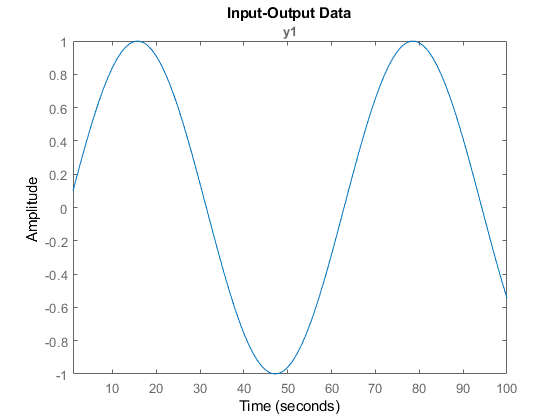

data = iddata(sin(0.1*[1:100])',[]);
plot(data)


sys = ar(data,2)


sys =
Discrete-time AR model:  A(z)y(t) = e(t)
  A(z) = 1 - 1.99 z^-1 + z^-2           
                                        
Sample time: 1 seconds
  
Parameterization:
   Polynomial orders:   na=2
   Number of free coefficients: 2
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                                  
Estimated using AR ('fb/now') on time domain data "data".
Fit to estimation data: 100% ( focus)                    
FPE: 5.256e-31, MSE: 5.05e-31                            


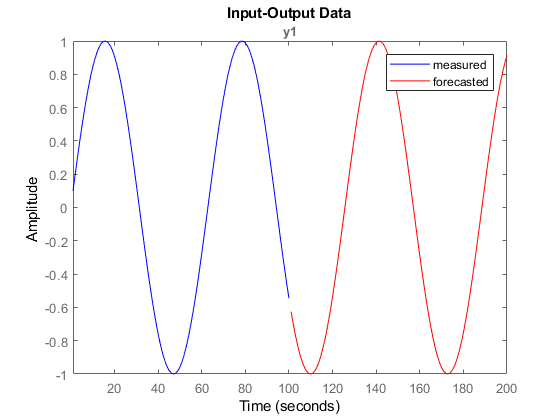


K = 100;
p = forecast(sys,data,K);


plot(data,'b',p,'r'), legend('measured','forecasted')

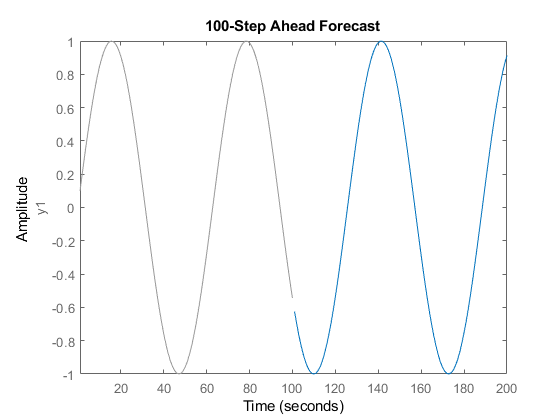

forecast(sys,data,K)

ntstool演示介绍